M08_50=readmatrix('C:\Users\yassi\Desktop\mesures\M08_50.CSV','Range',[6 1 125 3]);
M08_55=readmatrix('C:\Users\yassi\Desktop\mesures\M08_55.CSV','Range',[6 1 125 3]);
M08_60=readmatrix('C:\Users\yassi\Desktop\mesures\M08_60.CSV','Range',[6 1 125 3]);
M08_65=readmatrix('C:\Users\yassi\Desktop\mesures\M08_65.CSV','Range',[6 1 125 3]);
M08_70=readmatrix('C:\Users\yassi\Desktop\mesures\M08_70.CSV','Range',[6 1 125 3]);
M08_75=readmatrix('C:\Users\yassi\Desktop\mesures\M08_75.CSV','Range',[6 1 125 3]);
M08_80=readmatrix('C:\Users\yassi\Desktop\mesures\M08_80.CSV','Range',[6 1 125 3]);
M08_85=readmatrix('C:\Users\yassi\Desktop\mesures\M08_85.CSV','Range',[6 1 125 3]);
M08_90=readmatrix('C:\Users\yassi\Desktop\mesures\M08_90.CSV','Range',[6 1 125 3]);


## Calcul des valeurs complexes Z_b = R_b + jwL_b


nb_mesure_dist=9;
nb_mesure_frequence=120;
Zb=zeros(nb_mesure_frequence,nb_mesure_dist);
x = 0.5:0.05:0.9;
frequence = M08_90(:,1);

Zb(:,1)=M08_50(:,3)+M08_50(:,2)*2*pi.*frequence*1i;
Zb(:,2)=M08_55(:,3)+M08_55(:,2)*2*pi.*frequence*1i;
Zb(:,3)=M08_60(:,3)+M08_60(:,2)*2*pi.*frequence*1i;
Zb(:,4)=M08_65(:,3)+M08_65(:,2)*2*pi.*frequence*1i;
Zb(:,5)=M08_70(:,3)+M08_70(:,2)*2*pi.*frequence*1i;
Zb(:,6)=M08_75(:,3)+M08_75(:,2)*2*pi.*frequence*1i;
Zb(:,7)=M08_80(:,3)+M08_80(:,2)*2*pi.*frequence*1i;
Zb(:,8)=M08_85(:,3)+M08_85(:,2)*2*pi.*frequence*1i;
Zb(:,9)=M08_90(:,3)+M08_90(:,2)*2*pi.*frequence*1i;


## Caractérisation des bobines

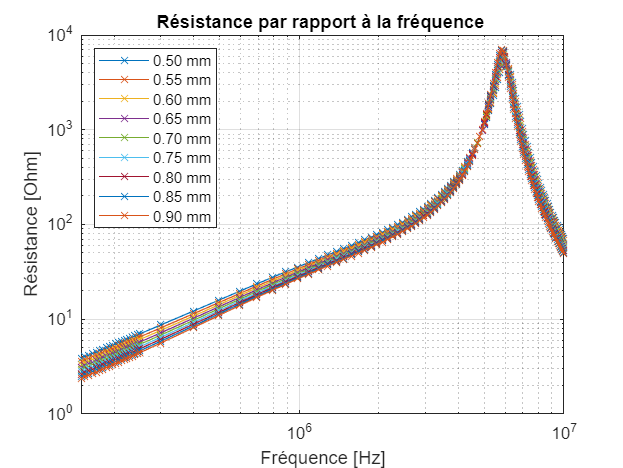

figure;
loglog(frequence,real(Zb),'-x');
xlabel('Fréquence [Hz]');
ylabel('Résistance [Ohm]');
title('Résistance par rapport à la fréquence ');
legend('0.50 mm', '0.55 mm', '0.60 mm', '0.65 mm', '0.70 mm', '0.75 mm', '0.80 mm', '0.85 mm', '0.90 mm', 'Location','northwest');
xlim([1.5e5 1e7]);
grid on;

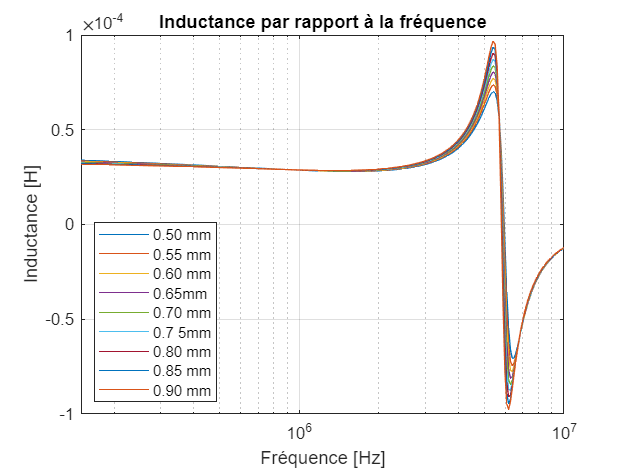


%mettre dans le rapport le zoom et inversion de l'inductance(ferromagnétique et conducteur)

semilogx(frequence,imag(Zb)./(2*pi*frequence))
xlabel('Fréquence [Hz]');
ylabel('Inductance [H]');
title('Inductance par rapport à la fréquence');
legend('0.50 mm', '0.55 mm', '0.60 mm', '0.65mm', '0.70 mm', '0.7 5mm', '0.80 mm', '0.85 mm', '0.90 mm', 'Location','southwest');
xlim([1.5e5 1e7]);
grid on;

## On fixe à présent la fréquence à 150 kHz :

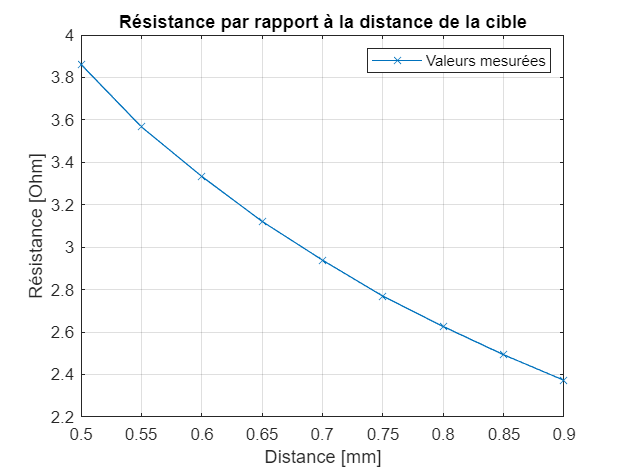

plot(x, real(Zb(1,:)), '-x')
xlabel('Distance [mm]');
ylabel('Résistance [Ohm]');
title('Résistance par rapport à la distance de la cible');
legend('Valeurs mesurées','Location','northeast');
grid on;

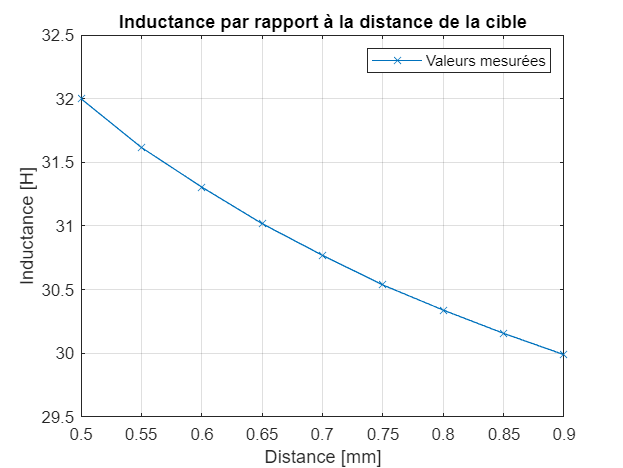

plot(x, imag(Zb(1,:)), '-x')
xlabel('Distance [mm]');
ylabel('Inductance [H]');
title('Inductance par rapport à la distance de la cible');
legend('Valeurs mesurées','Location','northeast');
grid on;

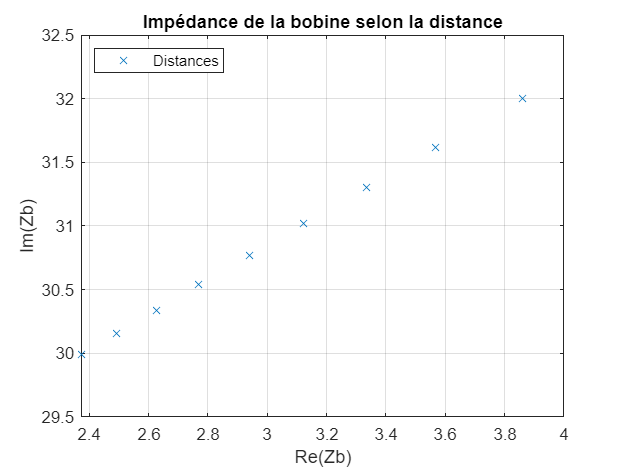

plot(real(Zb(1,:)),imag(Zb(1,:)),"x")
xlabel('Re(Zb)');
ylabel('Im(Zb)');
title('Impédance de la bobine selon la distance');
legend('Distances','Location','northwest');
grid on; 

%Les valeurs de l'impédance augmente selon la distance ! comparer

## Regression linéaire

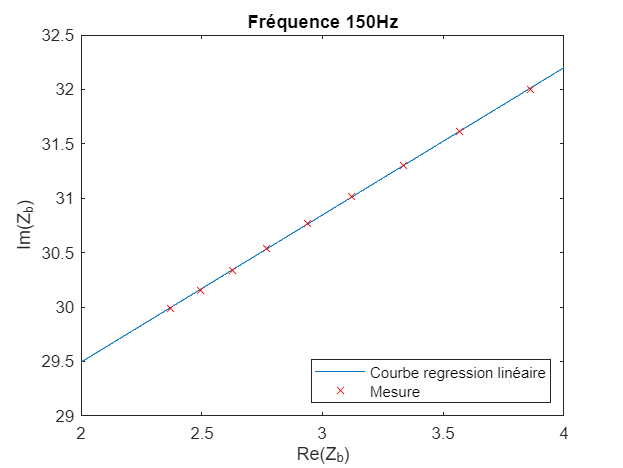

x=linspace(2,4,1000);
vect=polyfit(real(Zb(1,:)),imag(Zb(1,:)),1);

imZb=polyval(vect,x);
plot(x,imZb,"-",real(Zb(1,:)),imag(Zb(1,:)),"rx")
title('Fréquence 150Hz');
legend('Courbe regression linéaire','Mesure','location','southeast');
xlabel('Re(Z_{b})');
ylabel('Im(Z_{b})');


r=fitlm(real(Zb(1,:)),imag(Zb(1,:)));
R2=r.Rsquared.Ordinary

R2 = 0.9999

## Caractérisation de la bobine - sensibilité Sb pour x = 0.7 mm

Sb = abs(Zb(:, 4)-Zb(:, 6))/0.1;
[valeurMax, indiceMax] = max(Sb);
freq_ideal = frequence(indiceMax)

freq_ideal = 5.8848e+06

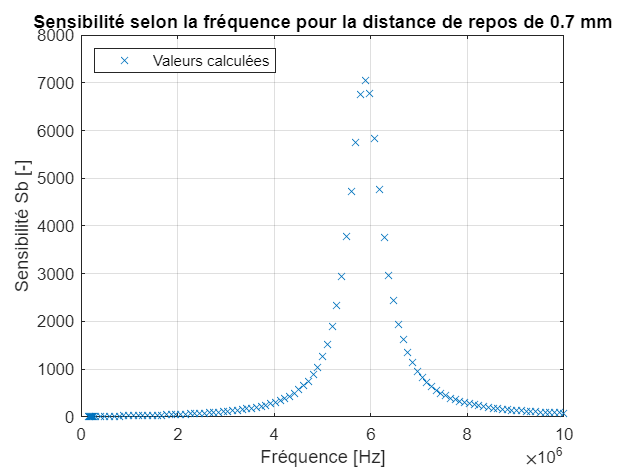

plot(frequence,Sb,"x")
xlabel('Fréquence [Hz]');
ylabel('Sensibilité Sb [-]');
title('Sensibilité selon la fréquence pour la distance de repos de 0.7 mm');
legend('Valeurs calculées','Location','northwest');
grid on;

## Calcul de la fréquence de résonance

fmes=139.391e3;
fth=150e3;
C=39*1e-9;

for i=1:3
Zbf0=interp1(frequence,Zb(:,5),fth,'linear','extrap');
Rb=real(Zbf0);
Lb=(imag(Zbf0))/(2*pi*fth);
wth=2*pi*fth;
Q=wth*Lb/Rb;
Lp=Lb*(1+1/(Q^2));
Rpth=Rb*(1+Q^2);
w01=sqrt((1/(Lb*C))-((Rb^2)/(Lb^2)));
fth=w01/(2*pi)
end

fth = 1.4032e+05

fth = 1.4019e+05

fth = 1.4019e+05


Rpth

Rpth = 309.2689

R0=305.7; % mesuré sur le multimetre
Lp

Lp = 3.3049e-05

fth

fth = 1.4019e+05

UextRms=2.4;

Umth=(4/pi)*(Rpth/(Rpth+R0))*UextRms

Umth = 1.5368

UmexpRms=1.01;
Umexp=UmexpRms*sqrt(2)

Umexp = 1.4284




Zbfth=interp1(frequence,Zb,fth,'linear','extrap')

Zbfth =    3.5710 +30.0482i   3.2960 +29.6760i   3.0789 +29.3763i   2.8859 +29.0972i   2.7160 +28.8545i   2.5551 +28.6284i   2.4267 +28.4374i   2.3009 +28.2602i   2.1889 +28.0958i


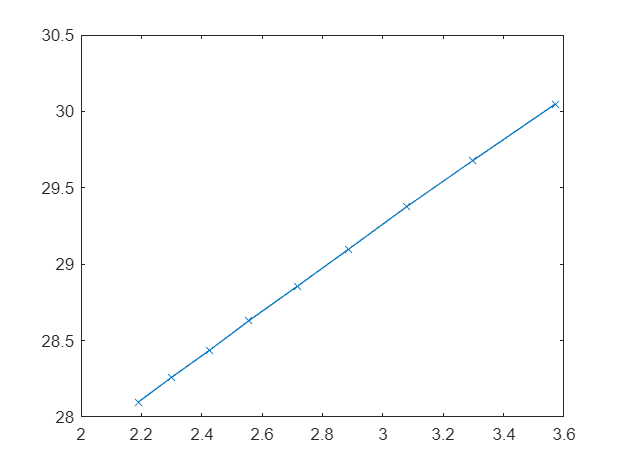


plot(real(Zbfth),imag(Zbfth),'-x')



a=1;
b=0;
c=1+1i*2*pi*fth*C*R0;
d=R0;
H=(a.*Zbfth+b)./(c.*Zbfth+d)

H =    0.4361 - 0.0934i   0.4587 - 0.0701i   0.4763 - 0.0477i   0.4910 - 0.0236i   0.5029 - 0.0000i   0.5128 + 0.0243i   0.5192 + 0.0464i   0.5244 + 0.0684i   0.5274 + 0.0897i


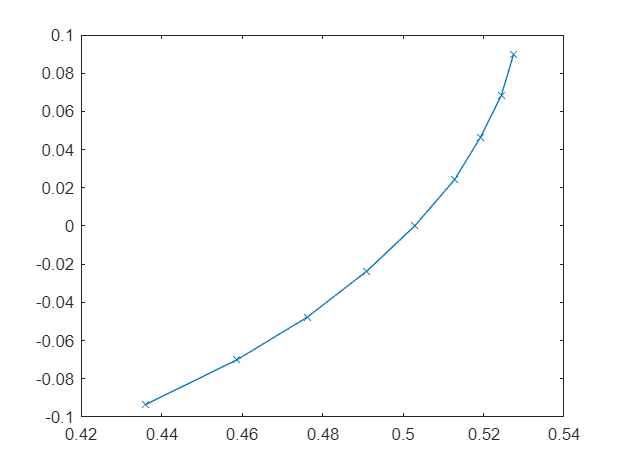


plot(real(H),imag(H),'-x')



x=real(H);
y=imag(H);

[xc,yc,R,a] = circfit(x,y)

xc = 0.2352

yc = 0.1207

R = 0.2938

a =    -0.4705
   -0.2414
   -0.0164


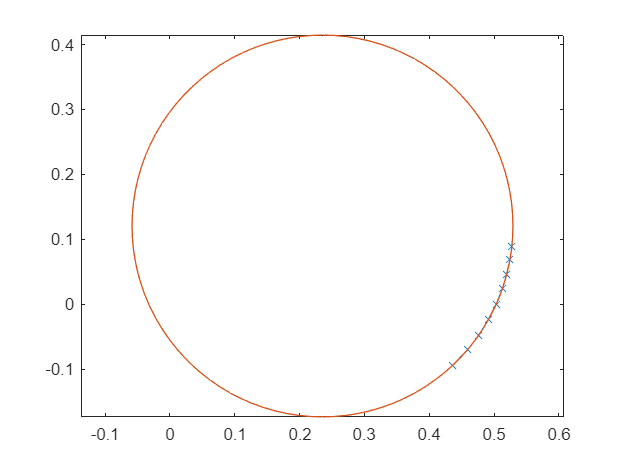

th=0:pi/50:2*pi;
x_unit = R * cos(th) + xc;
y_unit = R * sin(th) + yc;
plot(real(H),imag(H),'-x',x_unit,y_unit)
axis equal;